# Cinematica Directa 3DOF ANTRO

clc
clear

syms theta1 theta2 theta3 L1 a1 a2 a3 

A01=[cos(theta1) -sin(theta1)*cos(sym(pi/2)) sin(theta1)*sin(pi/2) a1*cos(theta1);
    sin(theta1) cos(sym(pi/2))*cos(theta1) -sin(pi/2)*cos(theta1) a1*sin(theta1);
    0 sin(pi/2) cos(sym(pi/2)) L1;
    0 0 0 1]

$$A01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 1 & 0 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


A12=[cos(theta2) -sin(theta2)*cos(0) sin(theta2)*sin(0) a2*cos(theta2);
    sin(theta2) cos(0)*cos(theta2) -sin(0)*cos(theta2) a2*sin(theta2);
    0 sin(0) cos(0) 0;
    0 0 0 1]

$$A12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & a_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & a_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


A23=[cos(theta3) -sin(theta3)*cos(0) sin(theta3)*sin(0) a3*cos(theta3);
    sin(theta3) cos(0)*cos(theta3) -sin(0)*cos(theta3) a3*sin(theta3);
    0 sin(0) cos(0) 0;
    0 0 0 1]

$$A23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & a_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & a_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


A_total_Antropo=simplify(A01*A12*A23)

$$A\_total\_Antropo = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sigma_{1}\\ \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{1}\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & L_{1}+a_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+a_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{1}+a_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+a_{2}\,\cos\left(\theta_{2}\right) \end{array}$$


%%JACOBIANO
x = A_total_Antropo(1,4);
y = A_total_Antropo(2,4);
z = A_total_Antropo(3,4);

Jv = jacobian([x y z],[theta1 theta2 theta3])

$$Jv = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(\theta_{1}\right)\,\sigma_{2} & -\cos\left(\theta_{1}\right)\,\sigma_{1} & -a_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\,\sigma_{2} & -\sin\left(\theta_{1}\right)\,\sigma_{1} & -a_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)\\ 0 & \sigma_{3}+a_{2}\,\cos\left(\theta_{2}\right) & \sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+a_{2}\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=a_{1}+\sigma_{3}+a_{2}\,\cos\left(\theta_{2}\right)\\ \sigma_{3}=a_{3}\,\cos\left(\theta_{2}+\theta_{3}\right) \end{array}$$


An1=(0*pi)/180;
An2=(0*pi)/180;
An3=(0*pi)/180;

Variables_antro = [theta1 theta2 theta3 L1 a1 a2 a3]

$$Variables\_antro = \left(\begin{array}{ccccccc} \theta_{1} & \theta_{2} & \theta_{3} & L_{1} & a_{1} & a_{2} & a_{3} \end{array}\right)$$

ValoresAngulosEslabones_antro =[0.58 -0.3977 1.81 0.19 0.06 0.15 0.17];

T_antro=subs(A_total_Antropo, Variables_antro, ValoresAngulosEslabones_antro);
T_antro=double(T_antro)

T_antro =     0.1320   -0.8260    0.5480    0.1883
    0.0865   -0.5412   -0.8365    0.1234
    0.9875    0.1578         0    0.2998
         0         0         0    1.0000


j_ANTRO=subs(Jv, Variables_antro, ValoresAngulosEslabones_antro);
j_ANTRO=double(j_ANTRO)

j_ANTRO =    -0.1234   -0.0918   -0.1404
    0.1883   -0.0602   -0.0920
         0    0.1651    0.0268




%%Posicion
P_antro=T_antro(1:3,4);

X_antro=P_antro(1)

X_antro = 0.1883

Y_antro=P_antro(2)

Y_antro = 0.1234

Z_antro=P_antro(3)

Z_antro = 0.2998

## Cinematica Inversa

syms Px Py Pz L1 a1 a2 a3 

P=[Px;Py;Pz];
theta_1=atan2(Py,Px);
Px_prima=sqrt((Px^2)+(Py^2));
R=sqrt(((Pz-L1)^2)+((Px_prima-a1)^2));
alpha=atan2((Pz-L1),(Px_prima-a1));
beta=acos(((R^2)+(a2^2)-(a3^2))/(2*a2*R));
gamma=acos(((a2^2)+(a3^2)-(R^2))/(2*a2*a3));
theta_2=alpha-beta;
theta_3=pi-gamma;

Variables_inverso = [Px Py Pz L1 a1 a2 a3]

$$Variables\_inverso = \left(\begin{array}{ccccccc} \mathrm{Px} & \mathrm{Py} & \mathrm{Pz} & L_{1} & a_{1} & a_{2} & a_{3} \end{array}\right)$$

Valorcoordenadasyeslabones=[0.1859 -0.1243 0.30 0.19 0.06 0.15 0.17];

theta1_val = double(subs(theta_1, Variables_inverso, Valorcoordenadasyeslabones));
theta2_val = double(subs(theta_2, Variables_inverso, Valorcoordenadasyeslabones));
theta3_val = double(subs(theta_3, Variables_inverso, Valorcoordenadasyeslabones));

fprintf('theta1 = %.4f rad\n', theta1_val);

theta1 = -0.5894 rad


fprintf('theta2 = %.4f rad\n', theta2_val);

theta2 = -0.3977 rad


fprintf('theta3 = %.4f rad\n', theta3_val);

theta3 = 1.8189 rad



%% Pix = 0.1859 PiY = 0.1243 PiZ =0.10
%% PfX = 0.1571 PfY = 0.0267 Pfz=0.085


## Planeacion de trayectorias

## 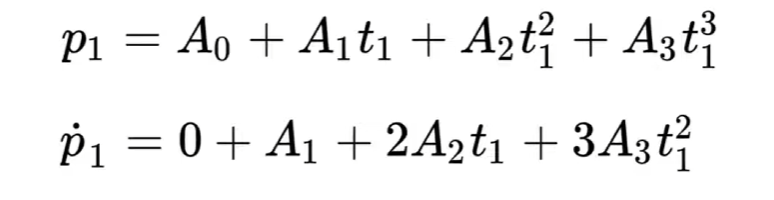

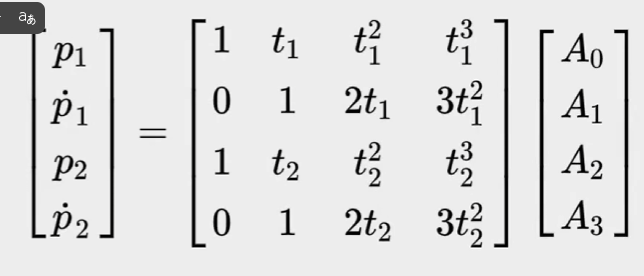

## Rampa de aceleración

t1=0; %tiempo inicial
t2=1; %tiempo final
% Puntos Iniciales
Pix = 0.2007; 
PiY = 0.0547; 
PiZ = 0.30;
% Puntos finales
PfX = 0.1859; 
PfY = 0.1243; 
Pfz=0.30;
% Velocidades
vel= 0.20; % magnitud [m/s]
D=sqrt((PfX-Pix)^2 + (PfY-PiY)^2 + (Pfz-PiZ)^2);
U_d=[PfX-Pix PfY-PiY Pfz-PiZ];
vec_vel=[vel*(U_d(1)/D) vel*(U_d(2)/D) vel*(U_d(3)/D)];
%Para X
vec_px=[Pix;vec_vel(1);PfX;0.1];
vec_t=[1 t1 t1^2 t1^3;
       0 1 2*t1 3*(t1^2);
       1 t2 t2^2 t2^3;
       0 1 2*t2 3*(t2^2)];
vec_Ax=inv(vec_t)*vec_px

vec_Ax =     0.2007
   -0.0416
   -0.0612
    0.0880


%Para Y
vec_py=[PiY;vec_vel(2);PfY;0.1];
vec_Ay=inv(vec_t)*vec_py

vec_Ay =     0.0547
    0.1956
   -0.2825
    0.1564


%Para Z
vec_pz=[PiZ;vec_vel(3);Pfz;0.1];
vec_Az=inv(vec_t)*vec_pz

vec_Az =     0.3000
         0
   -0.1000
    0.1000


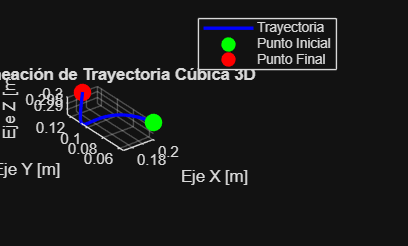


%Polinomio para cada eje
t = linspace(t1, t2, 100);
Polx = vec_Ax(1) + vec_Ax(2)*t + vec_Ax(3)*t.^2 + vec_Ax(4)*t.^3;
Poly = vec_Ay(1) + vec_Ay(2)*t + vec_Ay(3)*t.^2 + vec_Ay(4)*t.^3;
Polz = vec_Az(1) + vec_Az(2)*t + vec_Az(3)*t.^2 + vec_Az(4)*t.^3;

%Grafica de trayectoria
figure(1);
plot3(Polx, Poly, Polz, 'b', 'LineWidth', 2); 
hold on;
plot3(Pix, PiY, PiZ, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g'); % Inicio Verde
plot3(PfX, PfY, Pfz, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % Fin Rojo
grid on;
xlabel('Eje X [m]');
ylabel('Eje Y [m]');
zlabel('Eje Z [m]');
title('Planeación de Trayectoria Cúbica 3D');
legend('Trayectoria', 'Punto Inicial', 'Punto Final');
view(3); % Vista en perspectiva 3D
axis equal; 

## Jacobiano

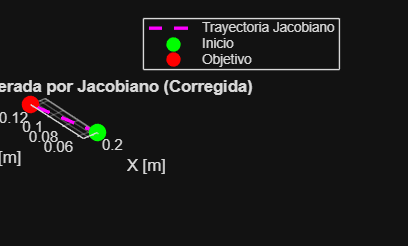

T=D/vel;
dt=0.02;
t = 0:dt:T;    % Vector de tiempo
n = length(t); 
Valorcoordenadasyeslabones=[Pix PiY PiZ 0.19 0.06 0.15 0.17];
theta1_val = double(subs(theta_1, Variables_inverso, Valorcoordenadasyeslabones));
theta2_val = double(subs(theta_2, Variables_inverso, Valorcoordenadasyeslabones));
theta3_val = double(subs(theta_3, Variables_inverso, Valorcoordenadasyeslabones));
q=[theta1_val; theta2_val; theta3_val];
q_hist = zeros(3, n);
pos_hist = zeros(3, n);
q_punto_hist=zeros(3, n);
vec_vel2 = vec_vel(:);
for k= 1:n
   ValoresAngulosEslabones_antro2 =[q(1) q(2) q(3) 0.19 0.06 0.15 0.17];
   T_antro2=subs(A_total_Antropo, Variables_antro, ValoresAngulosEslabones_antro2);
   T_antro2=double(T_antro2);
   X_actual=T_antro2(1:3,4);
   pos_hist(:, k) = X_actual;
   Jac=subs(Jv, Variables_antro, ValoresAngulosEslabones_antro2);
   Jac=double(Jac);
   q_punto=inv(Jac)*vec_vel2;
   q_punto_hist(:, k) = q_punto;
   q=q + q_punto*dt;
   q_hist(:, k) = q;
end

%%Graficas
figure(2); clf;
plot3(pos_hist(1,:), pos_hist(2,:), pos_hist(3,:), 'm--', 'LineWidth', 2, 'DisplayName', 'Trayectoria Jacobiano');
hold on; grid on;
plot3(pos_hist(1,1), pos_hist(2,1), pos_hist(3,1), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Inicio');
plot3(PfX, PfY, Pfz, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'Objetivo');
title('Trayectoria generada por Jacobiano (Corregida)');
xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
legend('show'); view(3); axis equal;

## Planeacion de trayectorias en el espacio de las articulaciones

%tiempos
t1=0;
v_limit = 1.6;
%q iniciales
Valorcoordenadasyeslabones2=[Pix PiY PiZ 0.19 0.06 0.15 0.17];
theta1_val2 = double(subs(theta_1, Variables_inverso, Valorcoordenadasyeslabones2));
theta2_val2 = double(subs(theta_2, Variables_inverso, Valorcoordenadasyeslabones2));
theta3_val2 = double(subs(theta_3, Variables_inverso, Valorcoordenadasyeslabones2));
qi=[theta1_val2; theta2_val2; theta3_val2];
%q finales
Valorcoordenadasyeslabones3=[PfX PfY Pfz 0.19 0.06 0.15 0.17];
theta1_val3 = double(subs(theta_1, Variables_inverso, Valorcoordenadasyeslabones3));
theta2_val3 = double(subs(theta_2, Variables_inverso, Valorcoordenadasyeslabones3));
theta3_val3 = double(subs(theta_3, Variables_inverso, Valorcoordenadasyeslabones3));
qf=[theta1_val3; theta2_val3; theta3_val3];
%Velocidades de junturas
qp_i=[0.1,0.1,0.1];
qp_f=[0,0,0];
tf_juntas = 1.5 * abs(qf - qi) / v_limit; 
tf = max(tf_juntas); 
%Matriz Polinomios
vec_t2=[1 t1 t1^2 t1^3;
       0 1 2*t1 3*(t1^2);
       1 tf tf^2 tf^3;
       0 1 2*tf 3*(tf^2)];
%Matriz Coeficientes
A_junta = zeros(4, 3); % Matriz para guardar coeficientes de las 3 juntas
for i = 1:3
    b = [qi(i); qp_i(i); qf(i); qp_f(i)];
    A_junta(:, i) = vec_t2 \ b; % solución del sistema de ecuaciones 
end
%Evaluacion de polinomios y velocidades
t = linspace(t1, tf, 100);
pos = zeros(length(t), 3);
vel_q = zeros(length(t), 3);

for i = 1:3
    % Polinomio de posición
    pos(:, i) = A_junta(1,i) + A_junta(2,i)*t + A_junta(3,i)*t.^2 + A_junta(4,i)*t.^3;
    % Polinomio de velocidad
    vel_q(:, i) = A_junta(2,i) + 2*A_junta(3,i)*t + 3*A_junta(4,i)*t.^2;
end

% Verificación de Velocidades Máximas
v_max_calculada = max(abs(vel_q));
fprintf('Velocidades máximas alcanzadas: q1:%.2f, q2:%.2f, q3:%.2f\n', v_max_calculada);

Velocidades máximas alcanzadas: q1:1.58, q2:0.10, q3:0.52


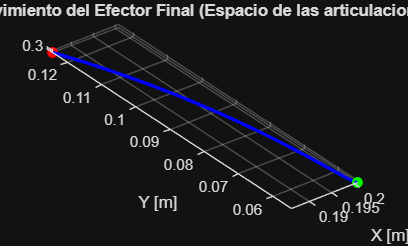


pos_cartesiana = zeros(length(t), 3);

for k=1:length(t)
   q_actual = pos(k, :);
   ValoresAngulosEslabones_antro3 =[q_actual(1) q_actual(2) q_actual(3) 0.19 0.06 0.15 0.17];
   T_antro3=subs(A_total_Antropo, Variables_antro, ValoresAngulosEslabones_antro3);
   T_antro3=double(T_antro3);
   pos_cartesiana(k,:)=T_antro3(1:3,4);
end

%%Grafica

figure(3);
plot3(pos_cartesiana(:,1), pos_cartesiana(:,2), pos_cartesiana(:,3), 'LineWidth', 2, 'Color', 'b');
hold on;
plot3(pos_cartesiana(1,1), pos_cartesiana(1,2), pos_cartesiana(1,3), 'go', 'MarkerFaceColor','g'); % Inicio
plot3(pos_cartesiana(end,1), pos_cartesiana(end,2), pos_cartesiana(end,3), 'ro', 'MarkerFaceColor','r'); % Fin
grid on; axis equal;
xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
title('Movimiento del Efector Final (Espacio de las articulaciones)');

## Guardar datos

writematrix(pos, 'Pos21.csv');